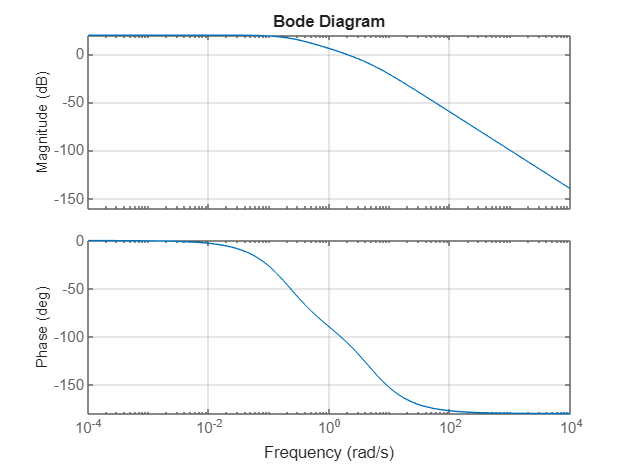

clc
clear all
close all
s=tf('s');

% Trabalho T2 - Projeto de Sistemas de Controle
% PUCRS - Escola Politécnica
% Prof. Dr. Rafael Castro
%
% Projeto de Compensadores Dinâmicos para Controle
% de Velocidade de Cruzeiro em Automóveis

%% Função de Transferência G(s) da Planta

% Insira sua matrícula (sem DV) dentro dos parênteses abaixo:
[ a , b , c ] = getvaluesT2( 20102977 );
% Atenção: não sobrescrever os parâmetros (a,b,c).

G = a/( s^2+b*s+c );
%                      |------|
% Pedal Acelerador --> | G(s) | --> Velocidade do Automóvel
%      [%]             |------|              [km/h]

%% Diagrama de Bode da Planta

% Espectro de frequência [rad/s]
W = 10.^(-4:0.01:4)';

figure(1)
bode(G,W)
grid on

%% Utilize este espaço para projetar seu controle
G


G =
 
       10
  -------------
  s^2 + 5 s + 1
 
Continuous-time transfer function.
Model Properties


% Infos do Bode antes do ganho K
w0 = 1.93;
Gm = inf;
Pm = 74.3;
Kp = 10; % Kp = 20dB
M = -20.9; % magnitude em 10 rad/s
K0 = 10^((-M)/20)

K0 = 11.0917

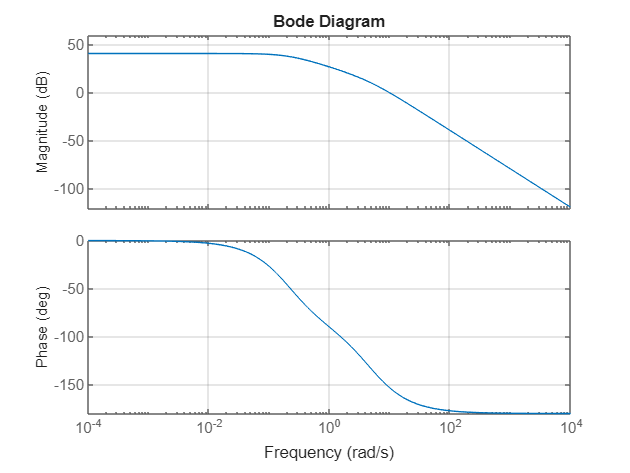

% Bode com o W0dB ajustado
w0_alvo = 10;
figure(2)
bode(K0*G, W)
grid on

% Projeto do compensador de avanço para atingir o requisito da margem de
% fase entre 60 e 70 graus

% Pm(alvo) = 65°+5°=70°
Pm_alvo = 26.8;
thetaM = 70-Pm_alvo

thetaM = 43.2000

beta = (1+sind(thetaM))/(1-sind(thetaM))

beta = 5.3401

polo_b = w0_alvo*sqrt(beta)

polo_b = 23.1086

zero_b = polo_b/beta

zero_b = 4.3274

Kb = sqrt(beta)

Kb = 2.3109

Kp_novo = Kp/Kb

Kp_novo = 4.3274

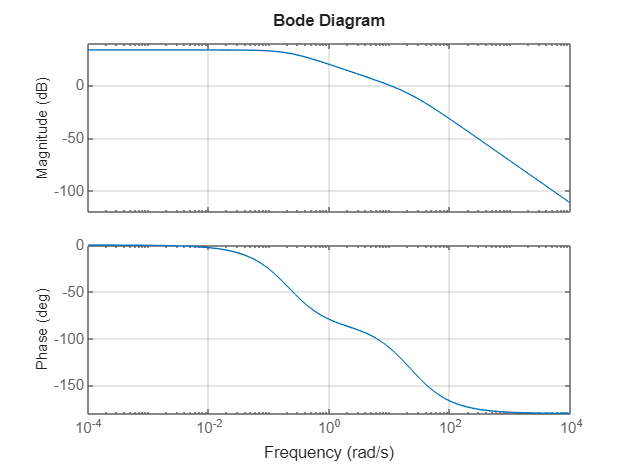

Cs = K0*(Kb*(s+zero_b)/(s+polo_b));

% Bode com requisitos de w0dB e fase de margem atingidos
figure(3)
bode(Cs*G, W)
grid on

% Projeto do compensador de atraso para atingir o requisito do erro em
% regime permanente de ep menor ou igual a 0,0001/Kp = 9999
erro = 0.1 / 1000;
Kp_alvo = (1/erro)-1

Kp_alvo = 9999

alpha = Kp_alvo / Kp_novo

alpha = 2.3106e+03

zero_a = w0_alvo/10

zero_a = 1

polo_a = zero_a/alpha

polo_a = 4.3278e-04

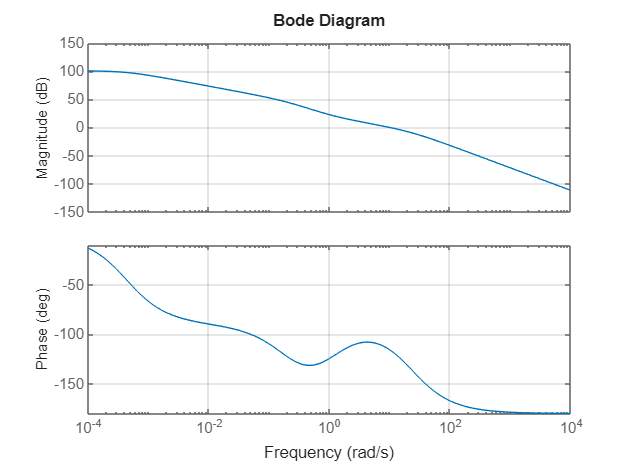

% Bode com requisitos de w0dB, margem de fase e erro em regime permanente
% atingidos
Cs = K0 * ((s+zero_a)/(s+polo_a)) * (Kb*(s+zero_b)/(s+polo_b));
figure(4)
bode(Cs*G, W)
grid on